%%%%%%%%%%%%%%%%%%%%%%
%%%playing around with upwind/downwind separation of receptors
%%%NEED TO ADD CODE FOLDER TO PATH
%%%created: 8-22-2022
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO %change to data folder

points = readtable("mapPoints.xlsx", "sheet", "From Matlab"); %grab receptor data

%grab met data
cd ../Met
rawMetSDK = readtimetable("Met_SDK.xlsx");
rawMetSSG = readtimetable("Met_SSG.xlsx"); %from Dobbins
rawMetSTER = readtimetable("Met_STER.xlsx"); %from FTY

%grab eto data
cd ../../Raw/'From AirVision'/
rawCanister = readtimetable("newCanisterData.xlsx", 'Sheet', 'ForMATLAB');
etoSSG = rawCanister(:, 1:7); %SSG has F sites, ug/m3
etoSTER = rawCanister(:, 21:31); %Ster has S sites, ug/m3
etoSDK = rawCanister(:, 10:20); %SDK, ppb
etoSDKEnt = etoSDK(:, [1:4, 9:10]); %SDK passive, ppb
etoSDKATEC = etoSDK(:, [5:8, 11]); %SDK pressurized, ppb

cd ../../ %return to data folder

%date bounds for time series
dateBoundSDK = datetime([2019, 2022], [6, 3], [14, 30]); %June 14, 2019 to March 30, 2022
dateBoundSTER = datetime([2019, 2022], [9, 4], [24, 23]); %Sept 24, 2019 to April 23, 2022
dateBoundSSG = datetime([2020, 2022], [1, 3], [16, 30]); %Jan 16, 2020 to March 30, 2022

%%%%%%%%%%%%%%%%%%%%%%
%%%upwind/downwind separation
%%%%%%%%%%%%%%%%%%%%%%
%%%pre-format for separation function

%%STER
temp = table2array(points(3:9, [5, 6])); %S1, S2, S3, S4, S5, S6, S7
%match structure of etoSSG but transposed
receptorsSTER = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(3, :)', temp(4, :)', temp(4, :)', ...
    temp(5, :)', temp(6, :)', temp(7, :)'];
receptorsSTER = array2table(receptorsSTER); %turn into table
%rename to match etoSSG
varNames = etoSTER.Properties.VariableNames;
receptorsSTER = renamevars(receptorsSTER, receptorsSTER.Properties.VariableNames, ...
    varNames);

%%SSG
temp = table2array(points(12:15, [5, 6])); %F1, F2, F3, F4
%match structure of etoSSG but transposed
receptorsSSG = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(4, :)', temp(4, :)'];
receptorsSSG = array2table(receptorsSSG); %turn into table
%rename to match etoSSG
varNames = etoSSG.Properties.VariableNames;
receptorsSSG = renamevars(receptorsSSG, receptorsSSG.Properties.VariableNames, ...
    varNames);

%%%upwind/downwind separation
%%UNIVERSAL
degUpwind = 90; % +- code for upwind
degDownwind = 90; % +- code for downwind
tol = 50; % minimum % in cone to qualify for inclusion

%%STER
degFromNSTER = table2array(receptorsSTER(2, :)); 
WDRSTER = rawMetSTER(:, 3); 
RRSTER = etoSTER;
%run function
[upwindSTER, downwindSTER, unbinnedSTER, percUpwindWDRSTER, percDownwindWDRSTER, statsSTER] = ...
    upwindDownwind(degFromNSTER, degUpwind, degDownwind, WDRSTER, tol, RRSTER);

%STER, FTY
WDRSSG = rawMetSSG(:, 3); 
[~, ~, ~, ~, ~, statsSTERFTY] = ...
    upwindDownwind(degFromNSTER, degUpwind, degDownwind, WDRSSG, tol, RRSTER);

%%SSG
degFromNSSG = table2array(receptorsSSG(2, :)); 
WDRSSG = rawMetSSG(:, 3); 
RRSSG = etoSSG;
%run function
[upwindSSG, downwindSSG, unbinnedSSG, percUpwindWDRSSG, percDownwindWDRSSG, statsSSG] = ...
    upwindDownwind(degFromNSSG, degUpwind, degDownwind, WDRSSG, tol, RRSSG);

%%%write to file

%%STER
writetimetable(upwindSTER, "upwindDownwindSTER.xlsx", "sheet", "upwind") %upwind
writetimetable(downwindSTER, "upwindDownwindSTER.xlsx", "sheet", "downwind") %downwind
writetimetable(unbinnedSTER, "upwindDownwindSTER.xlsx", "sheet", "unbinned") %unbinned
writetable(statsSTER, "upwindDownwindSTER.xlsx", "sheet", "stats", ...
    "WriteRowNames", true) %stats

%%SSG
writetimetable(upwindSSG, "upwindDownwindSSG.xlsx", "sheet", "upwind") %upwind
writetimetable(downwindSSG, "upwindDownwindSSG.xlsx", "sheet", "downwind") %downwind
writetimetable(unbinnedSSG, "upwindDownwindSSG.xlsx", "sheet", "unbinned") %unbinned
writetable(statsSSG, "upwindDownwindSSG.xlsx", "sheet", "stats", ...
    "WriteRowNames", true) %stats

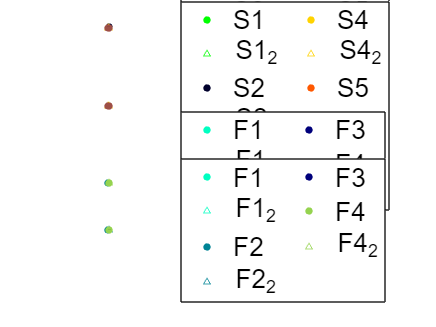

%%%%%%%%%%%%%%%%%%%%%%
%%%visualize everything
%%%%%%%%%%%%%%%%%%%%%%

%%%plot entire time series, ALL data 
colors = distinguishable_colors(13);
colors(7, 1) = 1; %tweak a little

figure
tiledlayout(4, 1, "TileSpacing", "compact")

%%1. Sterigenics upwind, convert to ppb
ax = nexttile;
hold on
grid on

variableNames = upwindSTER.Properties.VariableNames;
colorInds = [1, 1, 2, 2, 3, 3, 4, 4, 5, 6, 7];
for i = 1:length(variableNames)
    if ~contains(variableNames{i}, "_") %primary
        plot(upwindSTER.time, upwindSTER.(variableNames{i})/1.8, ...
            ".", "Color", colors(2 + colorInds(i), :), "MarkerSize", 15)
    else %collocated
        plot(upwindSTER.time, upwindSTER.(variableNames{i})/1.8, ...
            "^", "Color", colors(2 + colorInds(i), :), "MarkerSize", 4)
    end
end

xline(datetime(2020, 4, 8), '--k', "linewidth", 2) %controls installed

%lims
lims = ax.XLim;
ylim([-0.1 4.1]) %truncate 12 ppb value

%legend and labels
pbaspect([7, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("Upwind STER (ppbv)", "FontSize", 10)
legend(variableNames, "NumColumns", 2, "Location", "eastoutside")
hold off


%%2. Sterigenics downwind, convert to ppb
ax = nexttile;
hold on
grid on

variableNames = downwindSTER.Properties.VariableNames;
colorInds = [1, 1, 2, 2, 3, 3, 4, 4, 5, 6, 7];
for i = 1:length(variableNames)
    if ~contains(variableNames{i}, "_") %primary
        plot(downwindSTER.time, downwindSTER.(variableNames{i})/1.8, ...
            ".", "Color", colors(2 + colorInds(i), :), "MarkerSize", 15)
    else %collocated
        plot(downwindSTER.time, downwindSTER.(variableNames{i})/1.8, ...
            "^", "Color", colors(2 + colorInds(i), :), "MarkerSize", 4)
    end
end

xline(datetime(2020, 4, 8), '--k', "linewidth", 2) %controls installed

%lims
xlim(lims)
ylim([-0.1 4.1]) 

%legend and labels
pbaspect([7, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("Downwind STER (ppbv)", "FontSize", 10)
legend(variableNames, "NumColumns", 2, "Location", "eastoutside")
hold off


%%3. SSG upwind, convert to ppb
ax = nexttile;
hold on
grid on

variableNames = upwindSSG.Properties.VariableNames;
colorInds = [1, 1, 2, 2, 3, 4, 4];
for i = 1:length(variableNames)
    if ~contains(variableNames{i}, "_") %primary
        plot(upwindSSG.time, upwindSSG.(variableNames{i})/1.8, ...
            ".", "Color", colors(9 + colorInds(i), :), "MarkerSize", 15)
    else %collocated
        plot(upwindSSG.time, upwindSSG.(variableNames{i})/1.8, ...
            "^", "Color", colors(9 + colorInds(i), :), "MarkerSize", 4)
    end
end

xline(datetime(2021, 1, 26), '--k', "linewidth", 2) %controls installed

%lims
xlim(lims)
ylim([-0.1 4.1]) %truncate 12 ppb value

%legend and labels
pbaspect([7, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("Upwind SSG (ppbv)", "FontSize", 10)
legend(variableNames, "NumColumns", 2, "Location", "eastoutside")
hold off


%%4. SSG downwind, convert to ppb
ax = nexttile;
hold on
grid on

variableNames = downwindSSG.Properties.VariableNames;
colorInds = [1, 1, 2, 2, 3, 4, 4];
for i = 1:length(variableNames)
    if ~contains(variableNames{i}, "_") %primary
        plot(downwindSSG.time, downwindSSG.(variableNames{i})/1.8, ...
            ".", "Color", colors(9 + colorInds(i), :), "MarkerSize", 15)
    else %collocated
        plot(downwindSSG.time, downwindSSG.(variableNames{i})/1.8, ...
            "^", "Color", colors(9 + colorInds(i), :), "MarkerSize", 4)
    end
end

xline(datetime(2021, 1, 26), '--k', "linewidth", 2) %controls installed

%lims
xlim(lims)
ylim([-0.1 4.1]) 

%legend and labels
pbaspect([7, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("Downwind SSG (ppbv)", "FontSize", 10)
legend(variableNames, "NumColumns", 2, "Location", "eastoutside")
hold off

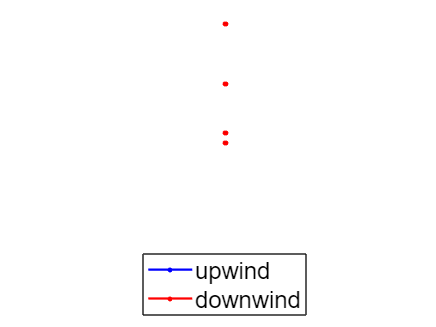

%%%plot average day connected with 2 plots, then month
figure
tiledlayout(4, 1, "TileSpacing", "compact")

%%1. Sterigenics, average on measurement days
ax1 = nexttile; %save for later
hold on
grid on

temp = mean(timetable2array(upwindSTER), 2, "omitnan"); %calculate mean upwind
inds = ~isnan(temp); %make continuous
plot(upwindSTER.time(inds), temp(inds), ".-b", "LineWidth", 1.5, ...
    "MarkerSize", 10)

temp = mean(timetable2array(downwindSTER), 2, "omitnan"); %calculate mean downwind
inds = ~isnan(temp); %make continuous
plot(downwindSTER.time(inds), temp(inds), ".-r", "LineWidth", 1.5, ...
    "MarkerSize", 10)

xline(datetime(2020, 4, 8), '--k', "linewidth", 2) %controls installed

%lims
lims = ax1.XLim; %save for later plots
ticks = ax1.XTick;
tickLabels = ax1.XTickLabel;
ylim([-0.1 4.1]) %truncate 12 ppb value

%legend and labels
pbaspect([7, 1, 1])
ax1.FontSize = 18;
ylabel("STER (ppbv)")
hold off


%%2. SSG, average on measurement days
ax = nexttile;
hold on
grid on

temp = mean(timetable2array(upwindSSG), 2, "omitnan"); %calculate mean upwind
inds = ~isnan(temp); %make continuous
plot(upwindSSG.time(inds), temp(inds), ".-b", "LineWidth", 1.5, ...
    "MarkerSize", 10)

temp = mean(timetable2array(downwindSSG), 2, "omitnan"); %calculate mean downwind
inds = ~isnan(temp); %make continuous
plot(downwindSSG.time(inds), temp(inds), ".-r", "LineWidth", 1.5, ...
    "MarkerSize", 10)

xline(datetime(2021, 1, 26), '--k', "linewidth", 2) %controls installed

%lims
xlim(lims)
ylim([-0.15 6.15]) 

%legend and labels
pbaspect([7, 1, 1])
ax.FontSize = 18;
ylabel("SSG (ppbv)")
hold off


%%3. Sterigenics, average on measurement months
ax = nexttile;
hold on
grid on

upwindMonthSTER = binByMonth(upwindSTER); %upwind, bin by month
times = datenum(upwindMonthSTER.Properties.RowTimes); %grab date nums
hl = boundedline(times, upwindMonthSTER.avgs, upwindMonthSTER.stds, ...
    '.-b', 'nan', 'gap', 'alpha');
hl.MarkerSize = 10; %change line aspects
hl.LineWidth = 1.5;

downwindMonthSTER = binByMonth(downwindSTER); %downwind, bin by month
times = datenum(downwindMonthSTER.Properties.RowTimes); %grab date nums
hl = boundedline(times, downwindMonthSTER.avgs, downwindMonthSTER.stds, ...
    '.-r', 'nan', 'gap', 'alpha');
hl.MarkerSize = 10; %change line aspects
hl.LineWidth = 1.5;

xline(datenum(datetime(2020, 4, 8)), '--k', "linewidth", 2) %controls installed

%lims
xlim(datenum(lims));
xticks(datenum(ticks));
ylim([-0.1 4.1]) %truncate 12 ppb value

%legend and labels
pbaspect([7, 1, 1])
ax.FontSize = 18;
ax.XTickLabel = tickLabels;
ylabel("STER (ppbv)")
hold off


%%4. SSG, average on measurement months
ax = nexttile;
hold on
grid on

upwindMonthSSG = binByMonth(upwindSSG); %upwind, bin by month
times = datenum(upwindMonthSSG.Properties.RowTimes); %grab date nums
hl = boundedline(times, upwindMonthSSG.avgs, upwindMonthSSG.stds, ...
    '.-b', 'nan', 'gap', 'alpha');
hl.MarkerSize = 10; %change line aspects
hl.LineWidth = 1.5;

downwindMonthSSG = binByMonth(downwindSSG); %downwind, bin by month
times = datenum(downwindMonthSSG.Properties.RowTimes); %grab date nums
hl = boundedline(times, downwindMonthSSG.avgs, downwindMonthSSG.stds, ...
    '.-r', 'nan', 'gap', 'alpha');
hl.MarkerSize = 10; %change line aspects
hl.LineWidth = 1.5;

xline(datenum(datetime(2021, 1, 26)), '--k', "linewidth", 2) %controls installed

%lims
xlim(datenum(lims));
xticks(datenum(ticks));
ylim([-0.15 6.15]) %truncate 12 ppb value

%legend and labels
pbaspect([7, 1, 1])
ax.FontSize = 18;
ax.XTickLabel = tickLabels;
ylabel("SSG (ppbv)")
hold off

%%legend
lg = legend(ax1, "upwind", "downwind");
lg.Layout.Tile = "South";